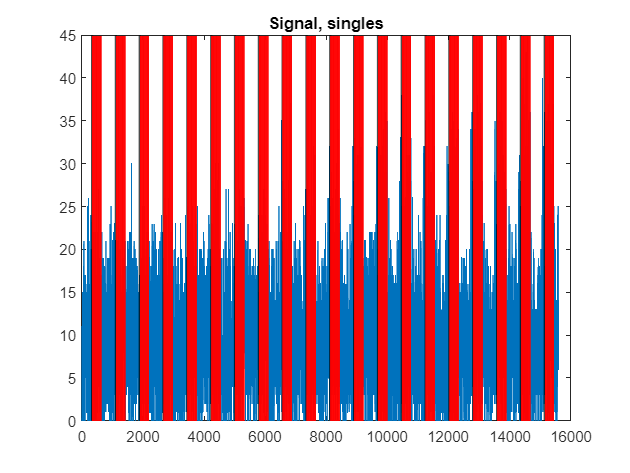

clear
load("tempNeigiamasRodiklisData.mat")

minAmplitude = 0.01;
maxAmplitude = 0.1;
stepCount = 20;

data_binary = [1 0 0 1 1 1]';
packet_bits = GenerateBits(data_binary);
singleSigLength = 780;
ADCsignalLong = zeros(1, stepCount*singleSigLength);
idealSignalLong = zeros(1, stepCount*singleSigLength);
for generuojama_amplitude_index = 1:stepCount
    generatedAmplitude = minAmplitude + (maxAmplitude - minAmplitude)/(stepCount-1+1) * (generuojama_amplitude_index-1);
    [idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule] = GenerateSignal(packet_bits, generatedAmplitude);
    copyIndexStart = singleSigLength*(generuojama_amplitude_index-1)+1;
    copyIndexLast = singleSigLength*(generuojama_amplitude_index);
    ADCsignalLong(copyIndexStart:copyIndexLast) = ADCsignal;
    idealSignalLong(copyIndexStart:copyIndexLast) = idealSignal(1:10:length(idealSignal));
end
%ADCsignalLong = idealSignalLong;

%Calculate preambule ending points
[preambule_ends_x, ~] = GenerateTargets(stepCount, convTypes(ConvolutionEnum.extended).expectedMaximum, length(ADCsignal), ADCsignalLong);
%Calculate bit ending points
bits_ends_duos = zeros(stepCount, length(packet_bits) / 2);
bits_ends_singles = zeros(stepCount, length(packet_bits));
for step = 1:stepCount
    for i = 1:length(bits_ends_duos(step, :))
        bits_ends_duos(step, i) = i * 20 + preambule_ends_x(step);
    end
    for i = 1:length(bits_ends_singles(step, :))
        bits_ends_singles(step, i) = i * 10 + preambule_ends_x(step);
    end
end


plot(ADCsignalLong, 'DisplayName', "Signal")
hold on
xline(preambule_ends_x, "black",'LineWidth', 1.5, 'DisplayName', "Preambule end")
for step = 1:stepCount 
    xline(bits_ends_singles(step, :), "red")
end
hold off
title("Signal, singles")

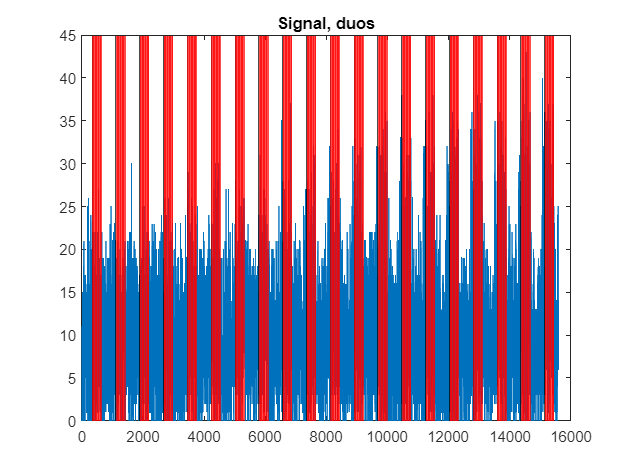


plot(ADCsignalLong, 'DisplayName', "Signal")
hold on
xline(preambule_ends_x, "black", 'DisplayName', "Preambule end")
for step = 1:stepCount 
    xline(bits_ends_duos(step, :), "red")
end
hold off
title("Signal, duos")

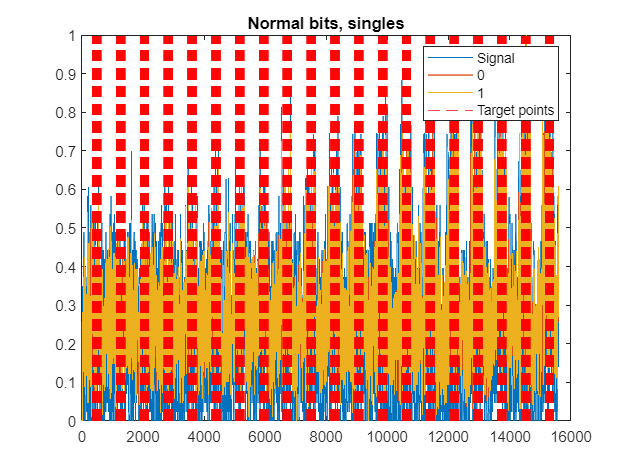

%Create bit masks
bit_1_mask = [1, 1, 1, 1, 1, 0, 0, 0, 0, 0];
bit_0_mask = [0, 0, 0, 0, 0, 1, 1, 1, 1, 1];
bit_masks_singles = [bit_0_mask; bit_1_mask];

bit_00_mask = [bit_0_mask, bit_0_mask];
bit_01_mask = [bit_0_mask, bit_1_mask];
bit_10_mask = [bit_1_mask, bit_0_mask];
bit_11_mask = [bit_1_mask, bit_1_mask];
bit_masks = [bit_00_mask; bit_01_mask; bit_10_mask; bit_11_mask];

bit_1_mask_negative = [1, 1, 1, 1, 1, -1, -1, -1, -1, -1];
bit_0_mask_negative = [-1, -1, -1, -1, -1, 1, 1, 1, 1, 1];
bit_00_mask_negative = [bit_0_mask_negative, bit_0_mask_negative];
bit_01_mask_negative = [bit_0_mask_negative, bit_1_mask_negative];
bit_10_mask_negative = [bit_1_mask_negative, bit_0_mask_negative];
bit_11_mask_negative = [bit_1_mask_negative, bit_1_mask_negative];
bit_masks_negative = [bit_00_mask_negative; bit_01_mask_negative; bit_10_mask_negative; bit_11_mask_negative];

%Correlate signal with individual bit masks
bit_corrs_singles = zeros(2, length(ADCsignalLong));
bit_corrs_duos = zeros(4, length(ADCsignalLong));
bit_corrs_duos_negative = zeros(4, length(ADCsignalLong));
for i = 1:4
    bit_corrs_duos(i, :) = GenerateConv(ADCsignalLong, bit_masks(i, :));
    bit_corrs_duos_negative(i, :) = GenerateConv(ADCsignalLong, bit_masks_negative(i, :));
end
for i = 1:2
    bit_corrs_singles(i, :) = GenerateConv(ADCsignalLong, bit_masks_singles(i, :));
end

plot(normalize(ADCsignalLong, "range"))
hold on
stairs(normalize(bit_corrs_singles(1, :), "range"))
stairs(normalize(bit_corrs_singles(2, :), "range"))
for step = 1:stepCount 
    xline(bits_ends_singles(step, :),'--', "color", "red")
end
hold off
legend("Signal", "0", "1", "Target points")
title("Normal bits, singles")

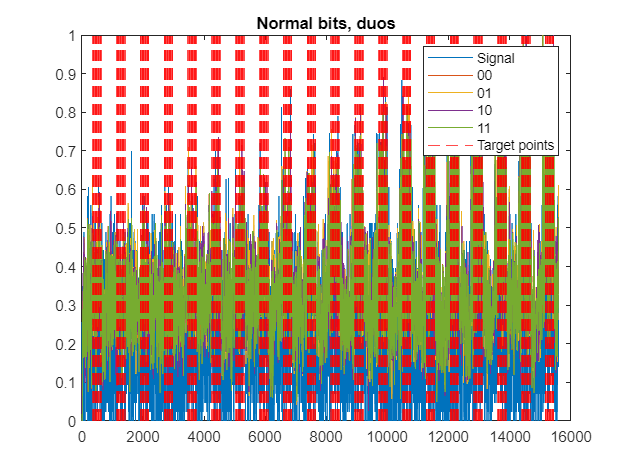


plot(normalize(ADCsignalLong, "range"))
hold on
plot(normalize(bit_corrs_duos(1, :), "range"))
plot(normalize(bit_corrs_duos(2, :), "range"))
plot(normalize(bit_corrs_duos(3, :), "range"))
plot(normalize(bit_corrs_duos(4, :), "range"))
for step = 1:stepCount 
    xline(bits_ends_duos(step, :),'--', "color", "red")
end
hold off
legend("Signal", "00", "01", "10", "11", "Target points")
title("Normal bits, duos")

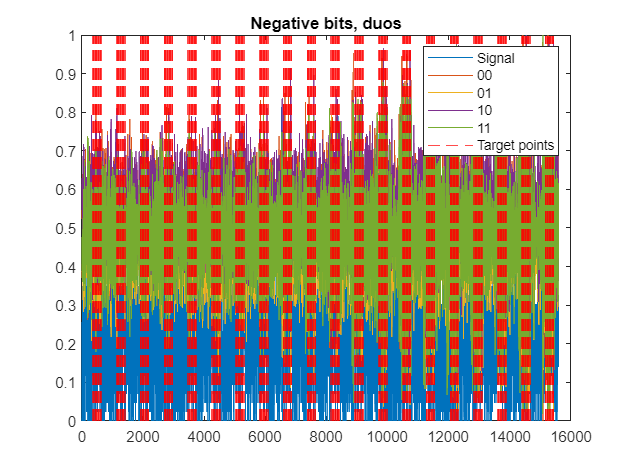

plot(normalize(ADCsignalLong, "range"), 'DisplayName', "Signal")
hold on
plot(normalize(bit_corrs_duos_negative(1, :), "range"))
plot(normalize(bit_corrs_duos_negative(2, :), "range"))
plot(normalize(bit_corrs_duos_negative(3, :), "range"))
plot(normalize(bit_corrs_duos_negative(4, :), "range"))
for step = 1:stepCount 
    xline(bits_ends_duos(step, :),'--', "color", "red")
end

hold off
legend("Signal", "00", "01", "10", "11", "Target points")
title("Negative bits, duos")

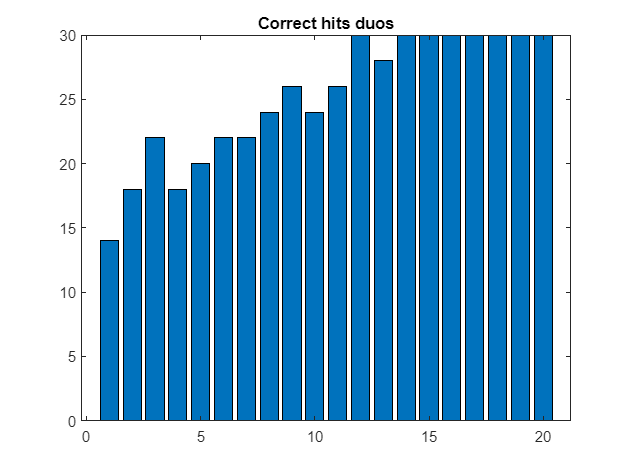

%Calculate correct hits duos by the step size
correct_hits_duos = zeros(1, stepCount);
correct_hits_duos_negative = zeros(1, stepCount);
correct_hits_duos_individual = zeros(1, length(bits_ends_duos(1, :)));
correct_hits_duos_all = 0;

for step = 1:stepCount
    hit_all = 1;
    for i = 1:length(bits_ends_duos(step, :))
        expected_bits = packet_bits(i*2-1 : i*2);
        %Find correlation with biggest value at target point
        biggest_index = -10000;
        biggest_value = -10000;
        for ii = 1:4
            if bit_corrs_duos(ii, bits_ends_duos(step, i)) > biggest_value
                biggest_value = bit_corrs_duos(ii, bits_ends_duos(step, i));
                biggest_index = ii;
            end
        end
        %Check if biggest value is expeted bits
        %TODO: Need to find a better way to do this
        if (biggest_index == 1) && isequal(expected_bits, [0, 0])
            correct_hits_duos(step) = correct_hits_duos(step) + 2;
            correct_hits_duos_individual(i) = correct_hits_duos_individual(i) + 1;
        elseif (biggest_index == 2) && isequal(expected_bits, [0, 1])
            correct_hits_duos(step) = correct_hits_duos(step) + 2;
            correct_hits_duos_individual(i) = correct_hits_duos_individual(i) + 1;
        elseif (biggest_index == 3) && isequal(expected_bits, [1, 0])
            correct_hits_duos(step) = correct_hits_duos(step) + 2;
            correct_hits_duos_individual(i) = correct_hits_duos_individual(i) + 1;
        elseif (biggest_index == 4) && isequal(expected_bits, [1, 1])
            correct_hits_duos(step) = correct_hits_duos(step) + 2;
            correct_hits_duos_individual(i) = correct_hits_duos_individual(i) + 1;
        else
            hit_all = 0;
        end
        
        %Find correlation with biggest value at target point with negative bits
        biggest_index = -10000;
        biggest_value = -10000;
        for ii = 1:4
            if bit_corrs_duos_negative(ii, bits_ends_duos(step, i)) > biggest_value
                biggest_value = bit_corrs_duos_negative(ii, bits_ends_duos(step, i));
                biggest_index = ii;
            end
        end
        %Check if biggest value is expeted bits
        %TODO: Need to find a better way to do this
        if (biggest_index == 1) && isequal(expected_bits, [0, 0])
            correct_hits_duos_negative(step) = correct_hits_duos_negative(step) + 2;
        elseif (biggest_index == 2) && isequal(expected_bits, [0, 1])
            correct_hits_duos_negative(step) = correct_hits_duos_negative(step) + 2;
        elseif (biggest_index == 3) && isequal(expected_bits, [1, 0])
            correct_hits_duos_negative(step) = correct_hits_duos_negative(step) + 2;
        elseif (biggest_index == 4) && isequal(expected_bits, [1, 1])
            correct_hits_duos_negative(step) = correct_hits_duos_negative(step) + 2;
        end
    end
    if hit_all == 1
        correct_hits_duos_all = correct_hits_duos_all + 1;
    end
end

bar(correct_hits_duos)
title("Correct hits duos")

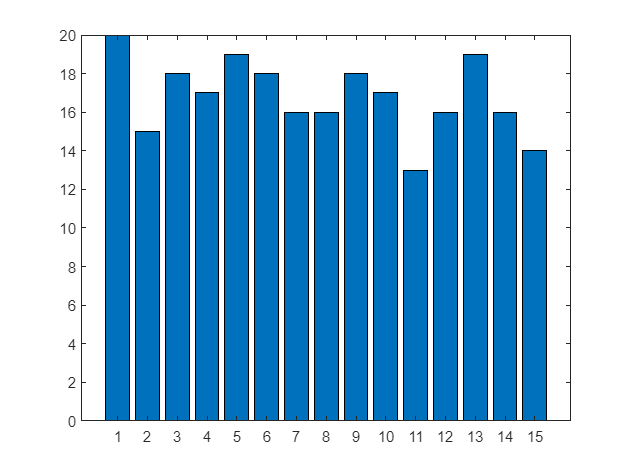

bar(correct_hits_duos_individual)

sum(correct_hits_duos)

ans = 504

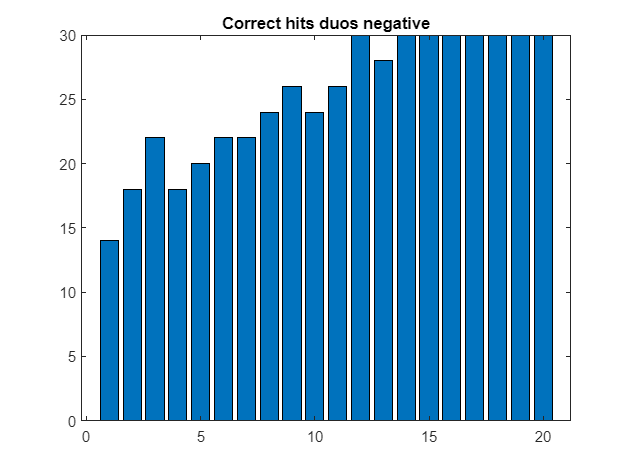

bar(correct_hits_duos_negative)
title("Correct hits duos negative")

sum(correct_hits_duos_negative)

ans = 504

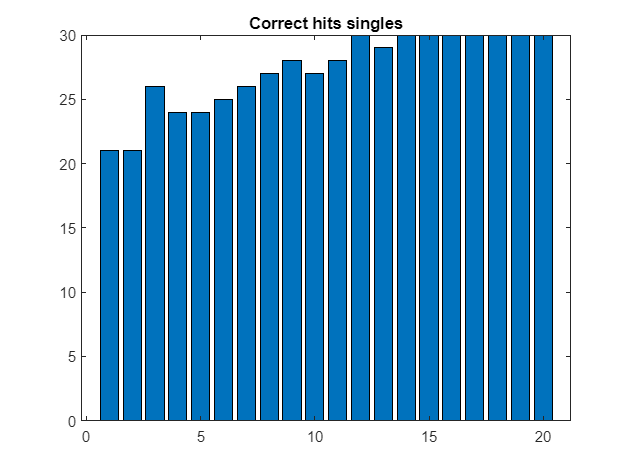

%Calculate correct hits singles
correct_hits_singles = zeros(1, stepCount);
correct_hits_singles_individual = zeros(1, length(bits_ends_singles));
correct_hits_singles_all = 0;

for step = 1:stepCount
    hit_all = 1;
    for i = 1:length(bits_ends_singles)
        expected_bits = packet_bits(i);
        %Find correlation with biggest value at target point
        biggest_index = -10000;
        biggest_value = -10000;
        for ii = 1:2
            if bit_corrs_singles(ii, bits_ends_singles(step, i)) > biggest_value
                biggest_value = bit_corrs_singles(ii, bits_ends_singles(step, i));
                biggest_index = ii;
            end
        end
        %Check if biggest value is expeted bits
        %TODO: Need to find a better way to do this
        if (biggest_index == 1) && (expected_bits == 0)
            correct_hits_singles(step) = correct_hits_singles(step) + 1;
            correct_hits_singles_individual(i) = correct_hits_singles_individual(i) + 1;
        elseif (biggest_index == 2) && (expected_bits == 1)
            correct_hits_singles(step) = correct_hits_singles(step) + 1;
            correct_hits_singles_individual(i) = correct_hits_singles_individual(i) + 1;
        else
            hit_all = 0;
        end
    end
    if hit_all == 1
        correct_hits_singles_all = correct_hits_singles_all + 1;
    end
end
bar(correct_hits_singles)
title("Correct hits singles")

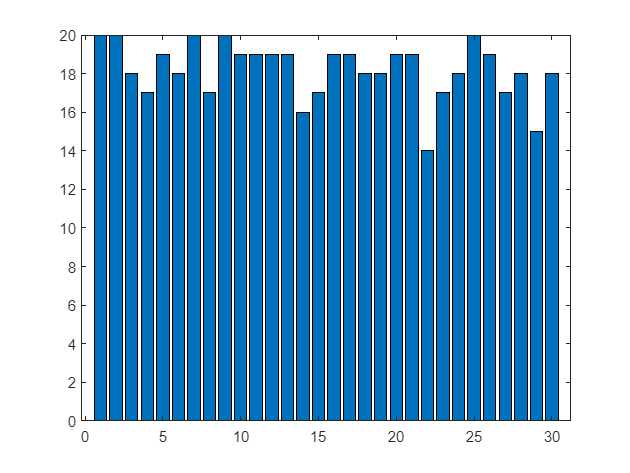

bar(correct_hits_singles_individual)

sum(correct_hits_singles)

ans = 546